# Lab 1 Playing with Sensitivity Functions

A plant is nominally modelled by $G\left(s\right)=\frac{10}{\left(s+10\right)\left(s+1\right)}$

The plant is controlled with a controller $C\left(s\right)$. A controller is designed in order to achieve a second order transfer function T1 with $w_0 =10\;\textrm{rad}\ldotp s^{-1}$and $\sigma =0\ldotp 6$


$$\textrm{T1}\left(s\right)=\frac{{10}^2 }{s^2 +2\times 0\ldotp 6\times \;10s+{10}^2 }$$


This baseline closed loop transfer function will be compared with T2, having different natural pulsation and damping factor

The goal is to analyse the sensitivity functions

s = tf('s');
G = 10/(s+1)/(s+10);
T1 = 100/(s^2+12*s+100);
wc =10

wc = 10

sigma = 1

sigma = 1

T2 = wc^2/(s^2+2*sigma*wc*s+wc^2);
L1=sprintf('design 1: wc=%2.2f ; sigma=%2.2f',10,0.6);
L2=sprintf('design 2: wc=%2.2f ; sigma=%2.2f',wc,sigma);

**Question 1**: what is the ratio of closed loop bandwidth with open loop bandwidth? Which controller is the more demanding?

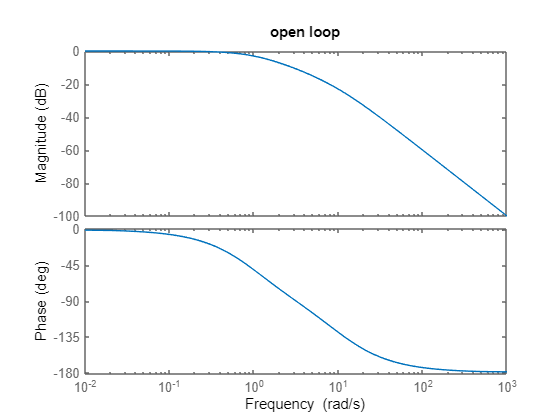

bode(G);title('open loop')

bandwidth(G)

ans = 0.9879

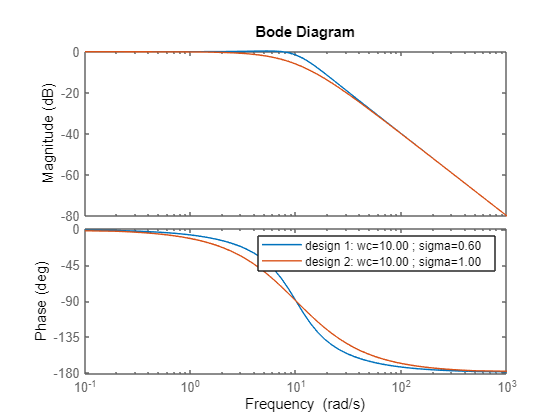

bode(T1,T2);legend(L1,L2);

bw1=bandwidth(T1)

bw1 = 11.4725

bw2=bandwidth(T2)

bw2 = 6.4229


% didn't understand the reasoning

(for wc=10 and sigma=1 the more demanding is T1, obtained because the damping objective is released)

(for wc=6 and sigma=0.6 the more demanding is T1, obtained because the  wc is higher)

**Question 2**: plot (and analyze) the reference to control sensitivity function bode diagram and the control response of a unitary step input.

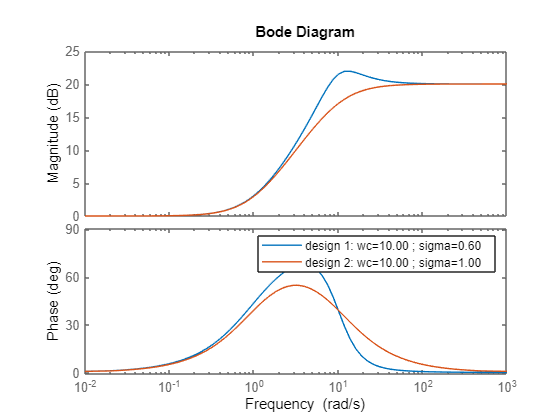

Sru1 = T1/G; %because S=K/(1+KG)
Sru2 = T2/G; 
bode(Sru1,Sru2);legend(L1,L2);

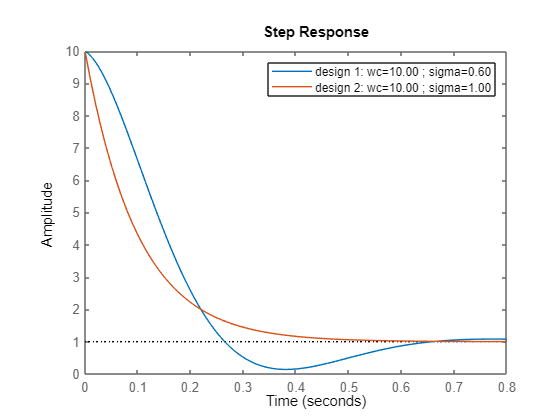

step(Sru1,Sru2);legend(L1,L2);

(for wc=10 and sigma=1 the Sru sensitivity function is  higher for controller 1, resulting in a  more demanding control effort.)

(for wc=6 and sigma=0.6 the Sru sensitivity function is higher, resulting in a higher control effort)

**Question 3**: compare the sensitivity function $S=\frac{1}{1+\textrm{CG}}$. Which conclusion can we draw for the robustness of the controller?

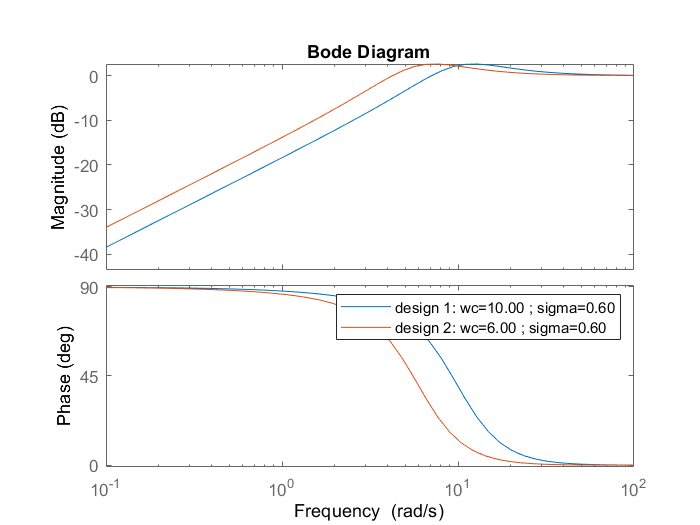

S1 = 1-T1; 
S2 = 1-T2;
bode(S1,S2);legend(L1,L2);

Peak of the sensitivity functions give an idea of the bandwidth. Max of the bandwidth give an idea of robustness (CG close to (-1,0) $\Longrightarrow$  CG+1 close to 0 $\Longrightarrow$ 1/(CG+1) large)

(for wc=10 and sigma=1 the max value in S is higher, meaning reduced robustness)

(for wc=6 and sigma=0.6 the max of the sensitivity function is unchanged, same robustness criteria)